# Drone Payload Structure Design and Analysis

In this project, you are optimizing drone arm design, including geometry and material selection, to maximize payload capacity while ensuring structural integrity under motor-induced loads. You will use MATLAB to perform force balance analysis and finite element modeling to quantitatively support your design solution.

Use this Live Script as a template to get started on your project solution. You may include helper functions at the bottom of this document or as separate files. For a tutorial on how to use Live Scripts, check out this [video](https://www.youtube.com/watch?v=hUXTyPYRidM).

**Suggested Tasks**

- Gather your starter assumptions and load the material properties into MATLAB.

- Propose at least two drone arm designs

- Perform a thrust-to-weight analysis to evaluate each of your designs across all material options. Your design must meet a minimum payload requirement and safety standards.

- Perform finite element analysis across all design and material options.

- Recommend a final design solution.

## Break Down the Problem

In the space below, define the problem statement:

The problem statement is defined as designing a quadcopter drone capable of maximizing payload capacity by proposing lightweight solutions that have structural integrity to withstand forces in flight while meeting safety requirements.  

List the requirements, constraints, and success criteria for the project:

For this project we must:

- Propose two different drone arm designs.

- Perform thrust-weight-analysis for each design and material option.

- Our design must support a 0.5 kg payload and meet a thrust-to-weight ratio of at least 2:1.

- Perform finite element analysis.

- Propose final design recommendation.

What is your proposed solution?

Our proposed solution is a hollow tube design and a beam of trusses design to maximize our payload capacity while remaining lightweight. We will use MATLAB and CAD to perform analysis and create 3D models of our designs.

List the steps you will need to take to achieve your proposed solution:

- Create drawings with dimensions and key details.

- Write matlab function to test thrust-to-weight analysis to ensure safety.

- Draw 3D models in CAD with out proposed dimensions.

- Upload our STL files to matlab and run a FEA on both of our separate designs to compare results such as max stress, factor of safety, and max displacement.

- Make a final recommendation based on the results.

What challenges do you face in the process of achieving the solution?

The challenges we might face are understanding drone flight basics and correctly applying motor loads to our model in FEA, interpreting results and evaluating tradeoff between strength and weight in order to propose our final recommendation.

## Task 1: Gather your starter assumptions and load material properties

Load the provided `droneArmMaterials.mat` file into MATLAB. This contains a data struct with the material properties for six different materials commonly used for drones (carbon fiber composite, aluminum alloy, fiberglass composite, PLA plastic, ABS plastic, and wood). For each material, you have been provided the following information:

- Density ($\rho$), in $\frac{\mathrm{kg}}{m^3 }$

- Young's Modulus ($E$) in Pa

- Poisson's ratio ($\nu$), unitless

- Yield strength, in Pa

- Average cost per meter in US dollars

For this project, you can assume the following design parameters:

- Quadcopter drone with 4 motors and 4 propellers

- Each motor can provide up to 1kg thrust

- Acceleration due to gravity: $g=9\ldotp 81\;\frac{m}{s^2 }$ 

- Total weight of the drone components without the arms or the payload: 1kg 

The breakdown of the weight of each drone component is as follow:

- Battery = 0.3kg

- Each motor = 65g, 4 motors = 0.26kg

- Each propeller = 10g, 4 propellers = 0.04 kg

- Each electronic speed controller = 30g, 4 electronic speed controllers = 0.12 kg

- Flight controller and electronics = 0.05kg

- Receiver/GPS = 0.03kg

- Drone frame (center body) excluding arms = 0.2kg

% ==================== Load "droneArmMaterials.mat" ====================
matPath = fullfile(pwd, 'data', 'droneArmMaterials.mat');
data = load(matPath);
materials = data.materials;

% ==================== Drone Specifications ====================
numMotors = 4; % Number of motors
numPropellers = 4; % Number of propellers
numElecContr = 4; % Number of electronic speed controllers (ESCs)
numArms = 4; % Number of frame arms
g = 9.81; % Acceleration due to gravity [m/s^2]

% ==================== Mass Breakdown ====================
thrustPerMotor = 1.0; % thrust of 1 motor [kg]
massBattery = 0.3; % mass of battery [kg]
massPerMotor = 0.065; % mass of 1 motor [kg]
massPerPropeller = 0.01; % mass of 1 propeller [kg]
massPerElecContr = 0.03; % mass of 1 ESC [kg]
massContr = 0.05; % mass of flight controller and electronics [kg]
massGPS = 0.03; % mass of receiver/gps [kg]
massCB = 0.2; % mass of center body excluding arms [kg]
massBase = 1.0; % total weight of the drone components without the arms or the payload [kg]



## Task 2: Propose at least two drone arm designs

Develop at least two distinct drone arm designs by drawing clear, neatly labeled sketches that show key geometric features, including:

- Overall shape (e.g. beam, tube, truss structure)

- Dimensions (length, width, thickness)

- Motor mount location

- Where the arm connects to the drone body 

The two designs should be meaningfully different from each other (e.g. different geometries or structural strategies) and not just small variations of the same idea.

Navigate to the 'Insert' tab and insert pictures of your sketches in the space below (hand-drawn or digital). Include a short design description for each sketch that includes:

- Geometry (e.g. solid beam, hollow tube, beam with trusses)

- Why you chose this design

- How it might perform under load

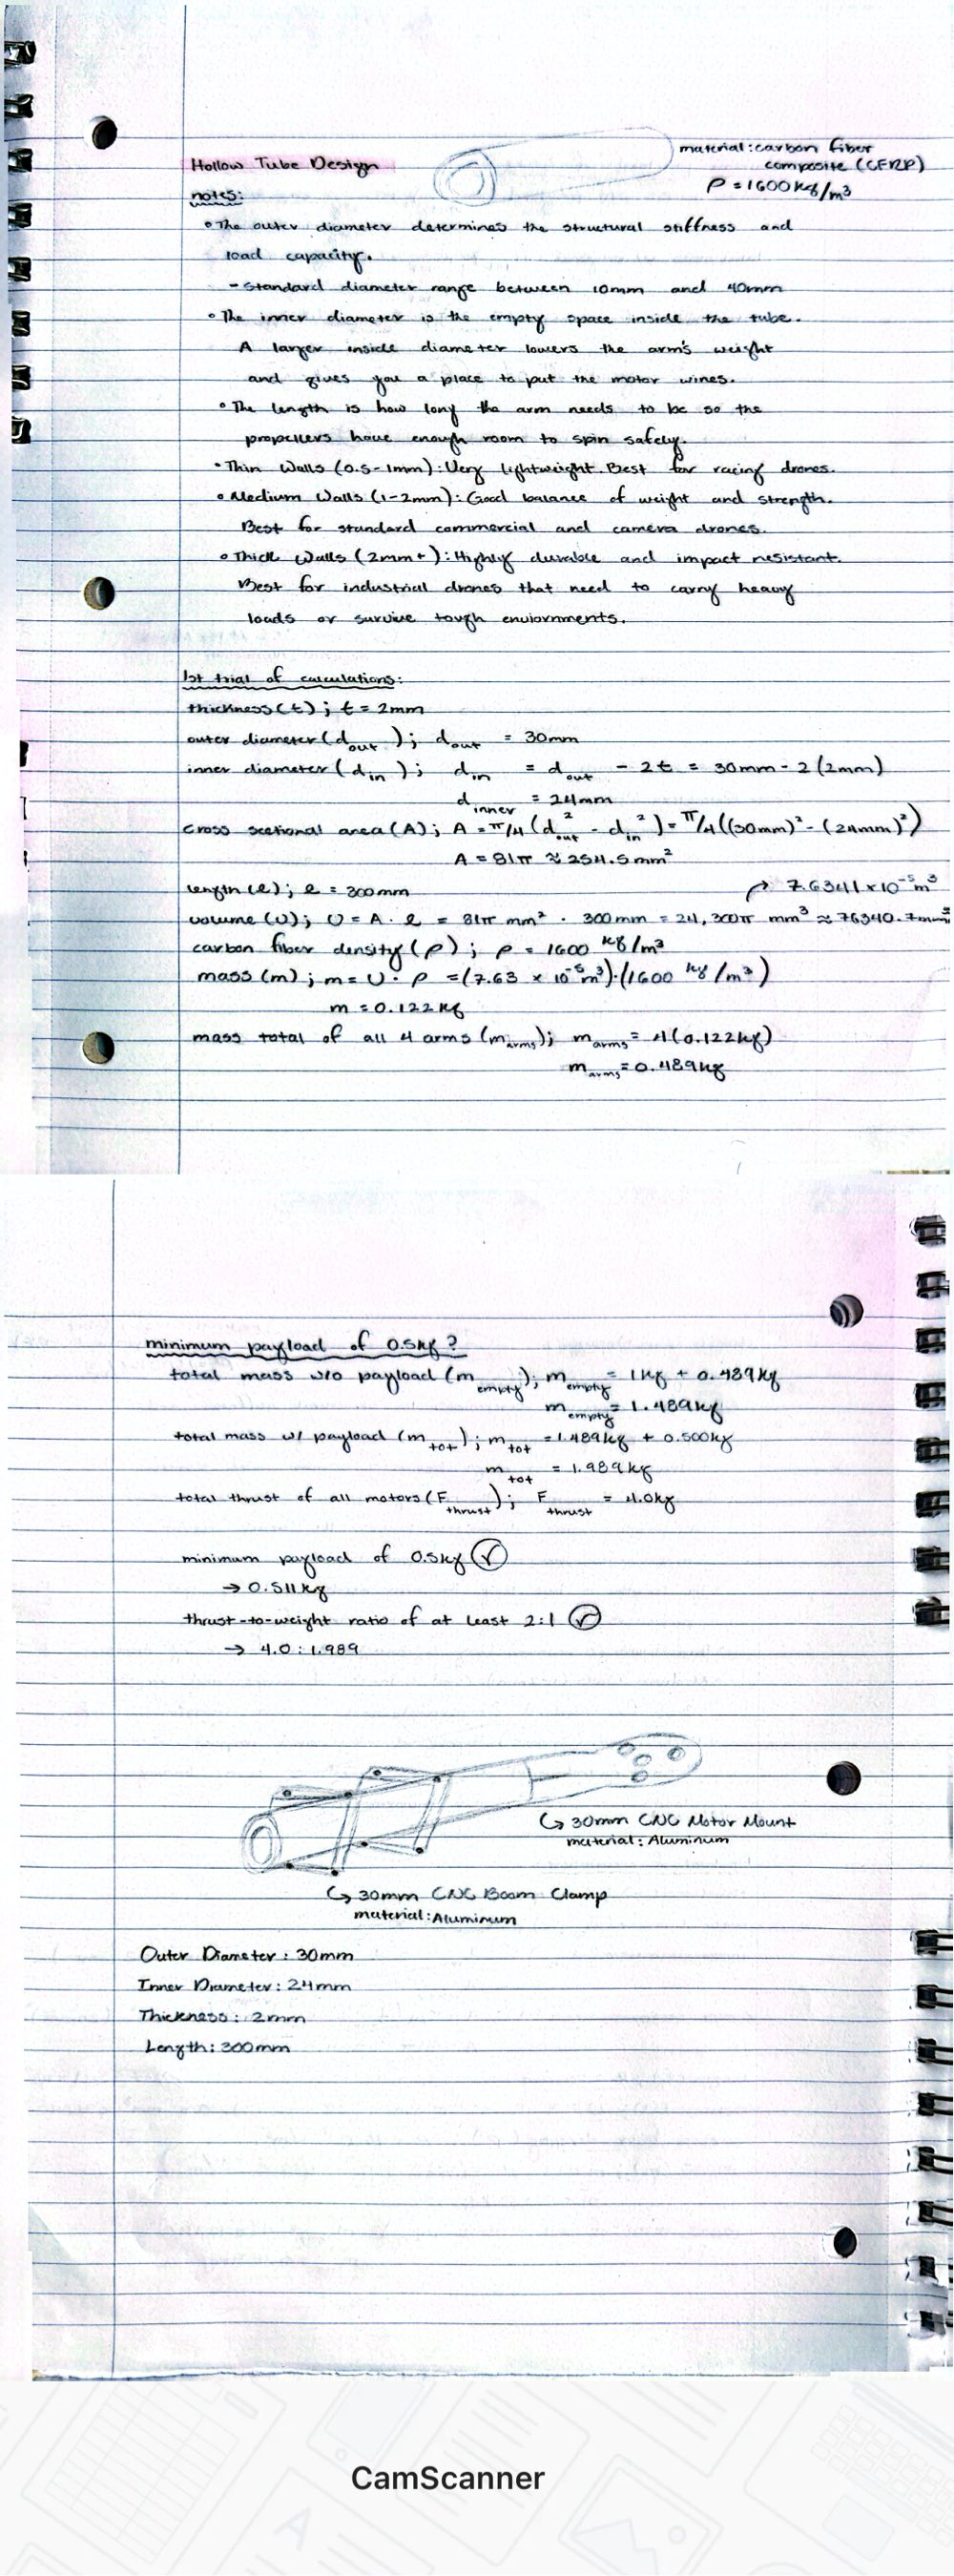

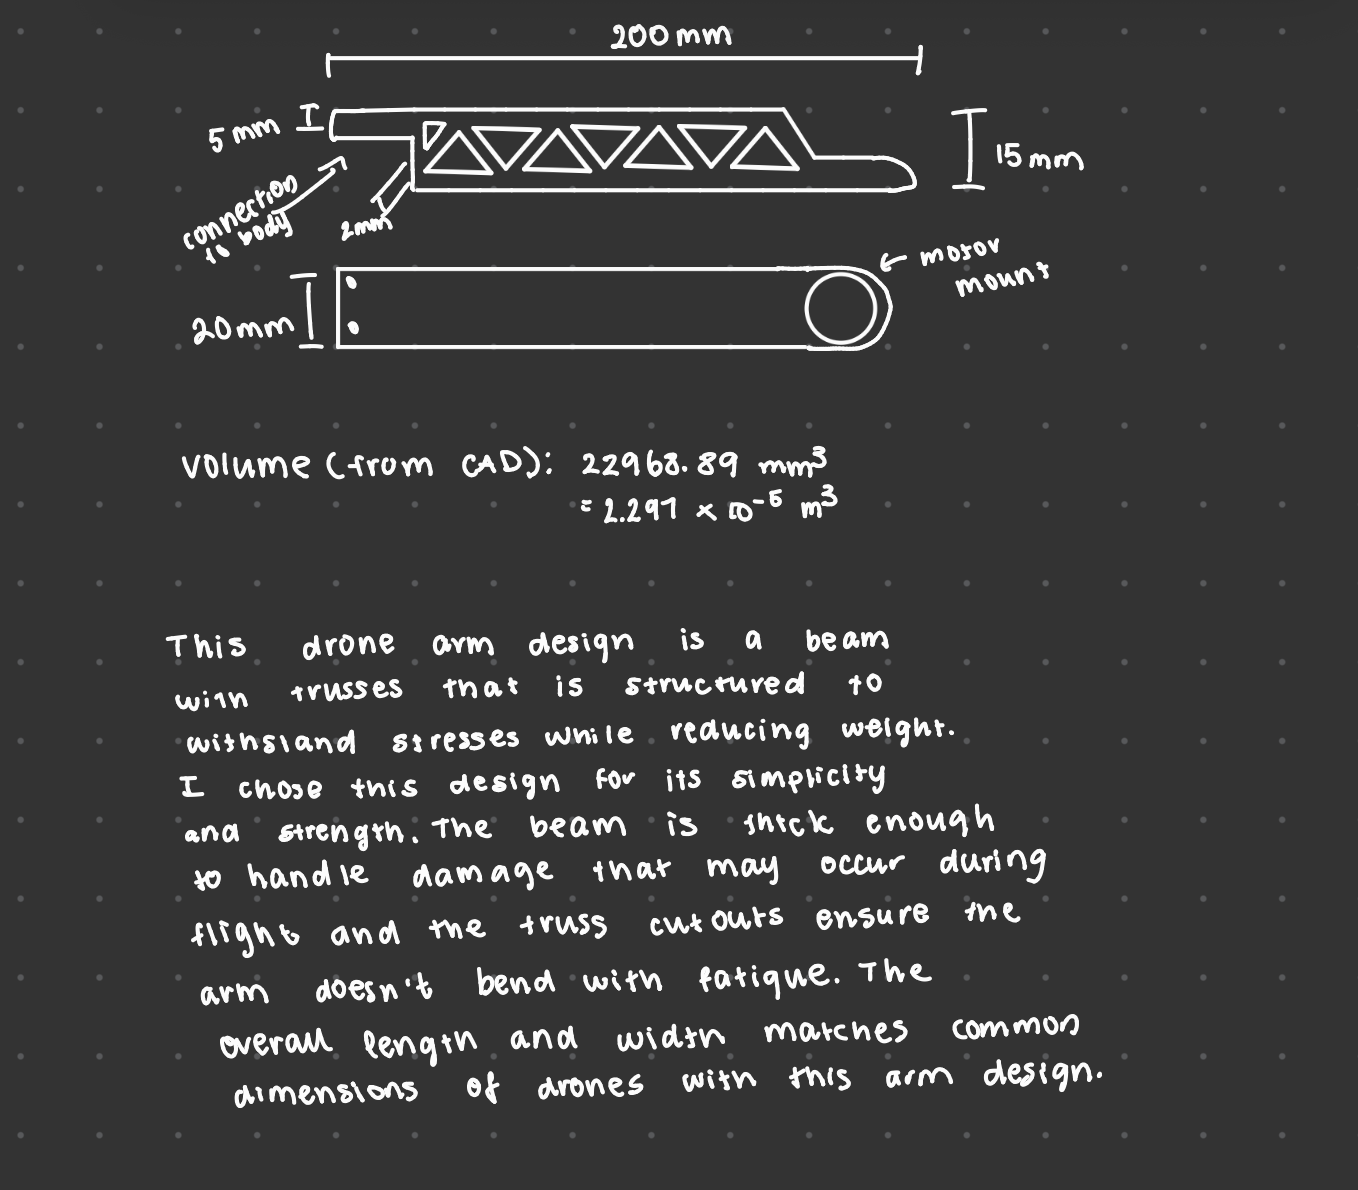

## Task 3: Perform thrust-to-weight analysis across all design and material options

Write a MATLAB function that will perform a thrust-to-weight analysis across all design and material options. This analysis will help you evaluate which drone arm design and which material optimizes payload capacity while meeting suggested safety requirements. 

- Your design must support a minimum payload of 0.5kg. 

- Your design must meet a thrust-to-weight ratio of at least 2:1 to ensure safe and stable flight. This safety standard is widely used in drone design. Conceptually, it means that the drone's maximum thrust must be at least twice its weight. This ensures stable hovering and maneuvering with a safety margin. Note that the thrust-to-weight safety margin is a system-level safety standard for drone flight that is distinct from the structural safety factor of the drone arms (which you will evaluate later through finite element analysis).

- Your goal is calculate maximum payload capacity for each design and material option (i.e. what is the heaviest payload your drone design could carry while still allowing the drone to safely take off?)

Ensure that the results of your analysis can be readily interpreted, e.g. in the form of a summary table or plot.

Note: if you have two drone arm designs, the expected output should be 12 payload capacity estimates (2 designs across 6 materials options).

% ==================== Geometry and Volume ====================
% Design 1: Hollow Tube Design
dOuter = 0.030; % Outer diameter [m]
dInner = 0.024; % Inner diameter [m]
thickArm = 0.003; % Wall thickness [m]
lengthArm = 0.300; % Arm length [m]

crossAreaTube = (pi/4) * ((dOuter)^2-(dInner)^2); % Cross sectional area [m^2]
volHollowTube = crossAreaTube * lengthArm; % Total volume of 1 arm [m^3]

% Design 2: Truss Design
volTruss = 0.00002297; % Taken from CAD [m^3]

% ==================== Setting up Structure Arrays ====================
% Design 1: Hollow Tube Design
designs(1).Name = 'HOLLOW TUBE DESIGN RESULT TABLE';
designs(1).Volume = volHollowTube;

% Design 2: Truss Design
designs(2).Name = 'TRUSS DESIGN RESULT TABLE';
designs(2).Volume = volTruss;

% ==================== Pre Allocated Arrays ====================
for i = 1:numel(designs)
    volArm = designs(i).Volume;

    numMaterials = numel(materials); % The number of elements (materials) in "droneArmMaterials.mat" data file
    matNameArr = strings(numMaterials, 1); % Column array for material names
    densityArr = zeros(numMaterials, 1); % Column array for densities
    massArmArr = zeros(numMaterials, 1); % Column array for single arm masses
    massEmptyArr = zeros(numMaterials, 1); % Column array for empty drone masses
    massPayloadArr = zeros(numMaterials, 1); % Column array for max payload capacities
    passStatusArr = false(numMaterials, 1); % Boolean array for payload requirement check

    % ==================== Payload Analysis Loop ====================
    for j = 1:numMaterials
        matNameArr(j) = materials(j).name;
        densityArr(j) = materials(j).rho_kg_m3;
        massArmArr(j) = volArm * densityArr(j); % Mass of 1 arm [kg]
        massEmptyArr(j) = massBase + (massArmArr(j) * numArms); % Total empty drone mass [kg]
        massPayloadArr(j) = (thrustPerMotor * (numMotors / 2)) - massEmptyArr(j); % Max payload capacity [kg]
        passStatusArr(j) = massPayloadArr(j) >= 0.5; % Check if payload is minimum 0.5 kg [true/false]
    end
    % ==================== Summary Result Table ====================
    matResultTable = table(matNameArr, densityArr, massArmArr, massEmptyArr, massPayloadArr, passStatusArr, ...
        'VariableNames', {'Material', 'Density (kg/m^3)', 'Single Arm Mass (kg)', 'Empty Drone Mass (kg)', 'Max Payload (kg)', 'Pass'});
    disp([designs(i).Name]);
    disp(matResultTable);
    fprintf('\n');
end

HOLLOW TUBE DESIGN RESULT TABLE


               Material                Density (kg/m^3)    Single Arm Mass (kg)    Empty Drone Mass (kg)    Max Payload (kg)    Pass 
    _______________________________    ________________    ____________________    _____________________    ________________    _____

    "Carbon Fiber Composite (CFRP)"          1600                 0.12215                 1.4886                0.51142         true 
    "Aluminum Alloy"                         2700                 0.20612                 1.8245                0.17552         false
    "Fiberglass Composite (GFRP)"            1900                 0.14505                 1.5802                0.41981         false
    "PLA Plastic"                            1250                0.095426                 1.3817                 0.6183      

TRUSS DESIGN RESULT TABLE


               Material                Density (kg/m^3)    Single Arm Mass (kg)    Empty Drone Mass (kg)    Max Payload (kg)    Pass 
    _______________________________    ________________    ____________________    _____________________    ________________    _____

    "Carbon Fiber Composite (CFRP)"          1600                0.036752                  1.147                0.85299         true 
    "Aluminum Alloy"                         2700                0.062019                 1.2481                0.75192         true 
    "Fiberglass Composite (GFRP)"            1900                0.043643                 1.1746                0.82543         true 
    "PLA Plastic"                            1250                0.028712                 1.1148                0.88515      

## Task 4: Perform finite element analysis across all design and material options

Perform finite element analysis (FEA) across all design and material options to evaluate the structural safety factor of your drone arm design. To simplify the task, you will perform the FEA only on a single drone arm.

Using a CAD software of your choice, first create a 3D model of one drone arm for each of your designs. Be sure your model can be exported as a STEP or STL file for analysis in MATLAB.

- Recommended CAD software options: Tinkercad, Onshape, Fusion 360, Solidworks (most have free versions)

Import your model into MATLAB and perform FEA. In your FEA model, you should model and apply two loads to the drone arm: upward thrust force from the motor and downward weight of the motor.

- Helpful resources: [online tutorial](https://matlabacademy.mathworks.com/details/introduction-to-finite-element-analysis-with-matlab/otmlfea), documentation for [Structural Mechanics](https://www.mathworks.com/help/pde/structural-mechanics.html) and [Partial Differentiation Equation Toolbox](https://www.mathworks.com/help/pde/index.html?s_tid=CRUX_lftnav), and [example workflow](https://www.mathworks.com/help/pde/ug/deflection-analysis-of-bracket-femodel.html)

For each design and material combination, you should report the overall maximum displacement, maximum stress, and factor of safety and include visualizations of the x-, y-, and z-displacement and Von Mises stress. Ensure that your results are presented for easy interpretation (e.g. present a table with numerical results, clearly labeled subplots for the visualizations).

- The factor of safety compares how strong a material is to how much stress it experiences, indicating whether a design is safe under the given loads. For this project use the equation: $\mathrm{FoS}=\frac{\mathrm{Material}\;\mathrm{Yield}\;\mathrm{Strength}\;\left(\mathrm{Pa}\right)}{\mathrm{Maximum}\;\mathrm{von}\;\mathrm{Mises}\;\mathrm{Stress}}$. Yield strength indicates how much stress a given material can withstand before permanently deforming. Maximum von Mises stress (derived from your FEA model) is a measure of how much stress your design experiences under the applied loads.

- A typical engineering safety margin for FoS is ~1.5-2+

- This [example](https://www.mathworks.com/help/pde/ug/deflection-analysis-of-bracket-femodel.html) demonstrates the plots you are asked to include in your results

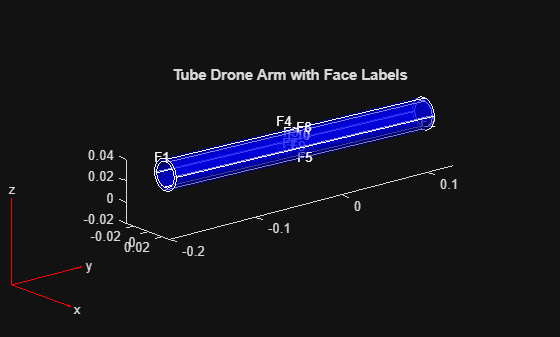

% ==================== Hollow Tube FEA ====================
% -------------------- Load and Create 3D Simulation Model --------------------
stlPathTube = fullfile('models', 'drone_arm_tube.stl');
gmTube = fegeometry(stlPathTube);
gmTube = scale(gmTube, 0.001); % Converts millimeters to meters

tubeModel = femodel(AnalysisType = 'structuralStatic', Geometry = gmTube);

% -------------------- Plot Geometry and Face Labels --------------------
% Front View (shows F1)
figure;
pdegplot(tubeModel, FaceLabels = 'on', FaceAlpha = 0.5, FaceColor = 'blue'); % Transparent faces (FaceAlpha = 0.5) to identify Face IDs
view(50, 18);
xlim([-0.03, 0.03]); ylim([-0.2, 0.13]); zlim([-0.02, 0.04]); camzoom(1.19);
title('Tube Drone Arm with Face Labels');

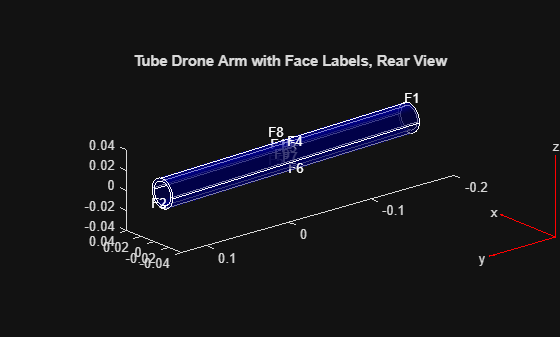

% Rear View (shows F2)
figure;
pdegplot(tubeModel, FaceLabels = 'on', FaceAlpha = 0.5, FaceColor = 'blue');
view(-130, 20); camzoom(1.20);
xlim([-0.04, 0.04]); ylim([-0.2, 0.13]); zlim([-0.04, 0.04]);
title('Tube Drone Arm with Face Labels, Rear View');

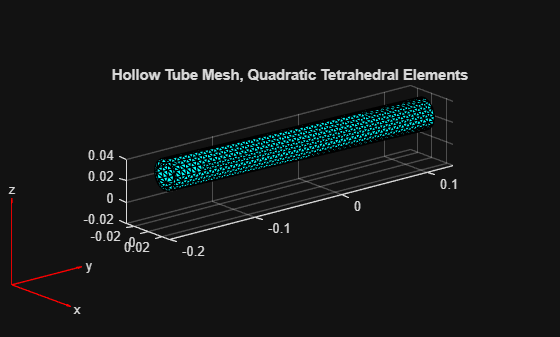

% -------------------- Boundary Conditions --------------------
tubeModel.FaceBC(1) = faceBC(Constraint = "fixed"); % Fix face connecting to drone body (Face 1)

thrustForce = thrustPerMotor * g; % Upward thrust from motor [N]
motorWeight = -(massPerMotor * g); % Downward weight due to motor [N]
netForce = thrustForce + motorWeight; % Net upward force along +Z [N]
netTractionTube = netForce / crossAreaTube; % Convert force to surface traction [N/m^2]

tubeModel.FaceLoad(2) = faceLoad(SurfaceTraction = [0; 0; netTractionTube]); % Apply net surface load to Face 2 (face where motor mounts)

% -------------------- Generate Mesh --------------------
tubeModel = generateMesh(tubeModel);

figure;
pdemesh(tubeModel);
title("Hollow Tube Mesh, Quadratic Tetrahedral Elements");
view(50, 18); xlim([-0.03, 0.03]); ylim([-0.2, 0.13]); zlim([-0.02, 0.04]); 
axis on; grid on; camzoom(1.19);

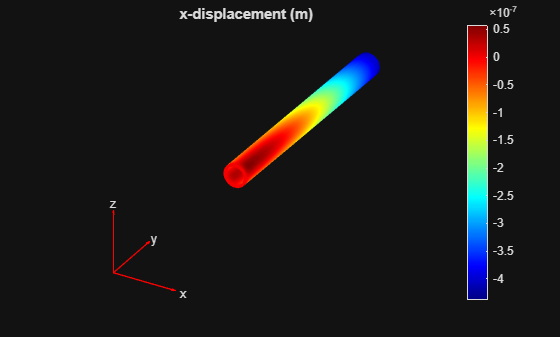

% -------------------- Pre Allocated Arrays --------------------
dispMaxTubeArr = zeros(numMaterials, 1); % Column array for max displacement
stressMaxTubeArr = zeros(numMaterials, 1); % Column array for max stress
yieldStrArr = zeros(numMaterials, 1); % Column array for yield strength
fosTubeArr = zeros(numMaterials, 1); % Column array for Factor of Safety

% -------------------- Loop Through All Materials --------------------
for j = 1:numMaterials
    matNameArr(j) = materials(j).name;
    yieldStrArr(j) = materials(j).yieldStrength_Pa;

    tubeModel.MaterialProperties = materialProperties( ...
        YoungsModulus = materials(j).E_Pa, ...
        PoissonsRatio = materials(j).nu, ...
        MassDensity = materials(j).rho_kg_m3);
    
    resultTube{j} = solve(tubeModel); % Solve FEA

    uxTube = resultTube{j}.Displacement.ux; % Displacement along x-axis
    uyTube = resultTube{j}.Displacement.uy; % Displacement along y-axis
    uzTube = resultTube{j}.Displacement.uz; % Displacement along z-axis

    dispMagTube = sqrt(uxTube.^2 + uyTube.^2 + uzTube.^2); % Magnitude of displacement [m]
    dispMaxTubeArr(j) = max(dispMagTube);
    stressMaxTubeArr(j) = max(resultTube{j}.VonMisesStress);
    fosTubeArr(j) = yieldStrArr(j) / stressMaxTubeArr(j);
end

% -------------------- Visualization Plots for Carbon Fiber Composite --------------------
% X-Displacement
figure;
pdeplot3D(resultTube{1}.Mesh, ColorMapData = resultTube{1}.Displacement.ux);
title('x-displacement (m)');
colormap('jet');

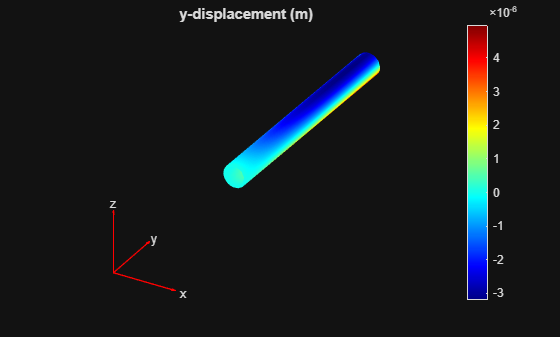

% Y-Displacement
figure;
pdeplot3D(resultTube{1}.Mesh, ColorMapData = resultTube{1}.Displacement.uy);
title('y-displacement (m)');
colormap('jet');

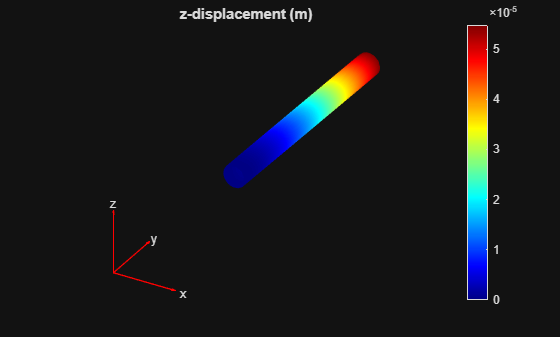

% Z-Displacement
figure;
pdeplot3D(resultTube{1}.Mesh, ColorMapData = resultTube{1}.Displacement.uz);
title('z-displacement (m)');
colormap('jet');

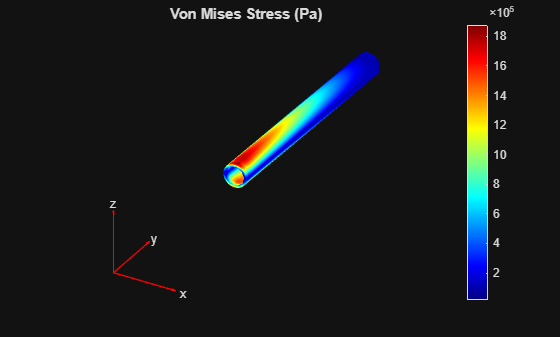

% Von Mises Stress
figure;
pdeplot3D(resultTube{1}.Mesh, ColorMapData = resultTube{1}.VonMisesStress);
title('Von Mises Stress (Pa)');
colormap('jet');

% -------------- Hollow Tube FEA Table --------------
feaResultTableTube = table(matNameArr, dispMaxTubeArr, stressMaxTubeArr, yieldStrArr, fosTubeArr, ...
    'VariableNames', {'Material', 'Max Displacement (m)', 'Max Stress (Pa)', 'Yield Strength (Pa)', 'Factor of Safety'});
disp('HOLLOW TUBE FEA RESULTS');

HOLLOW TUBE FEA RESULTS


disp(feaResultTableTube);

               Material                Max Displacement (m)    Max Stress (Pa)    Yield Strength (Pa)    Factor of Safety
    _______________________________    ____________________    _______________    ___________________    ________________

    "Carbon Fiber Composite (CFRP)"         5.4872e-05           1.8766e+06               6e+08               319.73     
    "Aluminum Alloy"                        5.5613e-05           1.8947e+06            2.75e+08               145.14     
    "Fiberglass Composite (GFRP)"           0.00015373           1.8663e+06               3e+08               160.74     
    "PLA Plastic"                            0.0010951           1.9167e+06               6e+07               31.304     
    "ABS Plastic"                            0.0019172           1.9089e+06               4e+07  

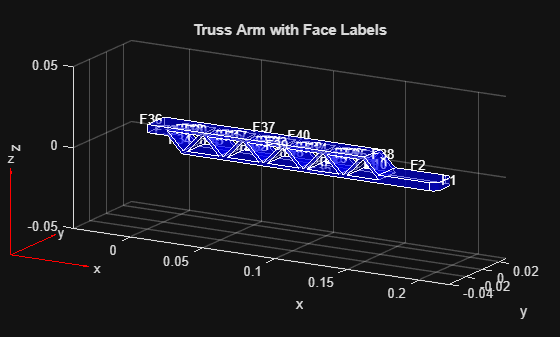

fprintf('\n');
% ==================== TRUSS ARM FEA ====================
% -------------------- Load and Create 3D Simulation Model --------------------
stlPathTruss = fullfile('models', 'Drone arm (truss) v2.stl');
gmTruss = fegeometry(stlPathTruss);
gmTruss = scale(gmTruss, 0.001); 
trussModel = femodel(AnalysisType = 'structuralStatic', Geometry = gmTruss);

% -------------------- Plot Geometry --------------------
% Front View (shows F1)
figure;
pdegplot(trussModel, 'FaceLabels', 'on', 'FaceAlpha', 0.5, FaceColor = 'blue');
title('Truss Arm with Face Labels');
xlabel('x'); ylabel('y'); zlabel('z'); grid on;
xlim([-0.04 0.22]); ylim([-0.04 0.03]); zlim([-0.05 0.05]); view([30 15]);

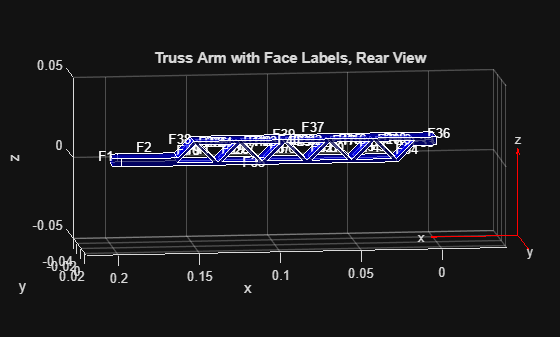

% Rear View (shows F2)
figure;
pdegplot(trussModel, 'FaceLabels', 'on', 'FaceAlpha', 0.7, FaceColor = 'blue');
title('Truss Arm with Face Labels, Rear View');
xlabel('x'); ylabel('y'); zlabel('z'); grid on;
xlim([-0.04 0.22]); ylim([-0.04 0.03]); zlim([-0.05 0.05]); view([173.1313 9.0246]);

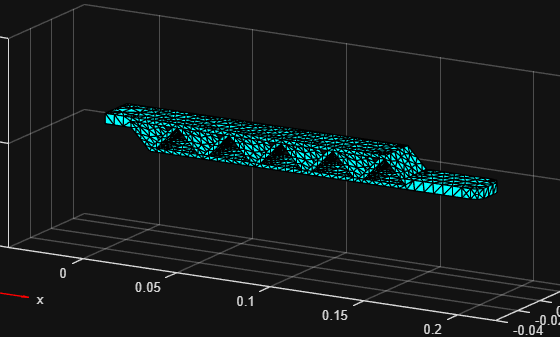

% -------------------- Boundary Conditions --------------------
trussModel.FaceBC(33) = faceBC(Constraint = 'fixed'); % Fix face connecting to drone body (Face 33)

crossAreaTruss = 0.02124756; % Taken from CAD [m^2]
netTractionTruss = netForce / crossAreaTruss;

trussModel.FaceLoad(2) = faceLoad(SurfaceTraction = [0; 0; netTractionTruss]); % Apply net surface load to Face 2 (face where motor mounts)

% -------------------- Generate Mesh --------------------
trussModel = generateMesh(trussModel);

figure;
pdemesh(trussModel);
title("Mesh with Quadratic Tetrahedral Elements");
view(50, 18); axis on; grid on; camzoom(1.19);
xlim([-0.04 0.22]); ylim([-0.04 0.03]); zlim([-0.05 0.05]); view([30 15]);

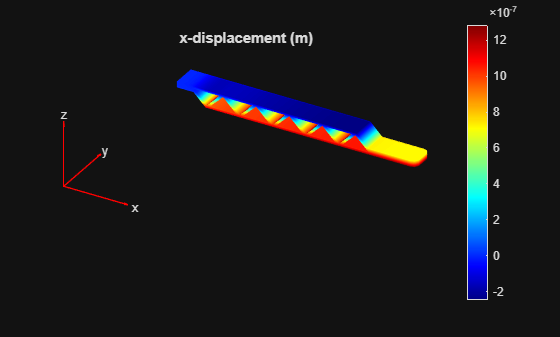

% -------------------- Pre Allocated Arrays --------------------
dispMaxTrussArr = zeros(numMaterials, 1); % Column array for max displacement
stressMaxTrussArr = zeros(numMaterials, 1); % Column array for max stress
fosTrussArr = zeros(numMaterials, 1); % Column array for Factor of Safety

% -------------------- Loop Through All Materials --------------------
for j = 1:numMaterials
    matNameArr(j) = materials(j).name;
    yieldStrArr(j) = materials(j).yieldStrength_Pa;

    trussModel.MaterialProperties = materialProperties( ...
        YoungsModulus = materials(j).E_Pa, ...
        PoissonsRatio = materials(j).nu, ...
        MassDensity = materials(j).rho_kg_m3);

    resultsTruss{j} = solve(trussModel); % Solve FEA

    uxTruss = resultsTruss{j}.Displacement.ux; % Displacement along x-axis
    uyTruss = resultsTruss{j}.Displacement.uy; % Displacement along y-axis
    uzTruss = resultsTruss{j}.Displacement.uz; % Displacement along z-axis

    dispMagTruss = sqrt(uxTruss.^2 + uyTruss.^2 + uzTruss.^2); % Magnitude of displacement [m]
    dispMaxTrussArr(j) = max(dispMagTruss);
    stressMaxTrussArr(j) = max(resultsTruss{j}.VonMisesStress);
    fosTrussArr(j) = yieldStrArr(j) / stressMaxTrussArr(j);
end

% -------------------- Visualization Plots for Carbon Fiber Composite --------------------
figure;
pdeplot3D(resultsTruss{1}.Mesh, ColorMapData = resultsTruss{1}.Displacement.ux);
title('x-displacement (m)');
colormap('jet');

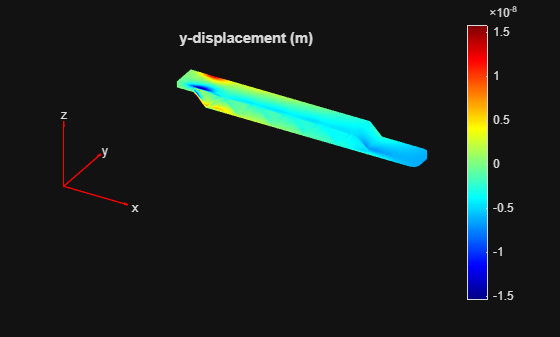

figure;
pdeplot3D(resultsTruss{1}.Mesh, ColorMapData = resultsTruss{1}.Displacement.uy);
title('y-displacement (m)');
colormap('jet');

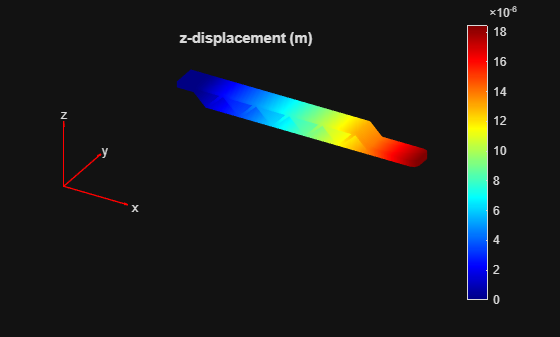

figure;
pdeplot3D(resultsTruss{1}.Mesh, ColorMapData = resultsTruss{1}.Displacement.uz);
title('z-displacement (m)');
colormap('jet');

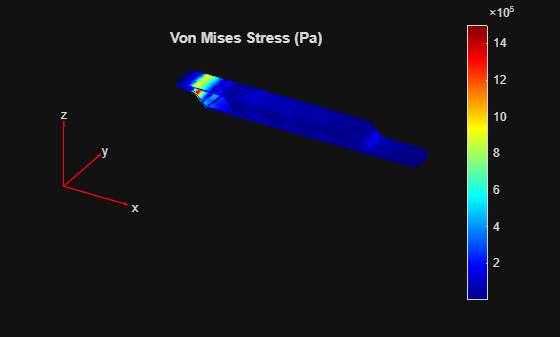

figure;
pdeplot3D(resultsTruss{1}.Mesh, ColorMapData = resultsTruss{1}.VonMisesStress);
title('Von Mises Stress (Pa)');
colormap('jet');

% -------------- Truss FEA Table --------------
feaResultTableTruss = table(matNameArr, dispMaxTrussArr, stressMaxTrussArr, yieldStrArr, fosTrussArr, ...
    'VariableNames', {'Material', 'Max Displacement (m)', 'Max Stress (Pa)', 'Yield Strength (Pa)', 'Factor of Safety'});
disp('TRUSS FEA RESULTS');

TRUSS FEA RESULTS


disp(feaResultTableTruss);

               Material                Max Displacement (m)    Max Stress (Pa)    Yield Strength (Pa)    Factor of Safety
    _______________________________    ____________________    _______________    ___________________    ________________

    "Carbon Fiber Composite (CFRP)"         1.8531e-05           1.5005e+06               6e+08               399.87     
    "Aluminum Alloy"                        1.8557e-05           1.4883e+06            2.75e+08               184.78     
    "Fiberglass Composite (GFRP)"            5.228e-05           1.5088e+06               3e+08               198.83     
    "PLA Plastic"                           0.00036031            1.476e+06               6e+07               40.651     
    "ABS Plastic"                           0.00063392           1.4801e+06               4e+07  

fprintf('\n');

## Interpretation of Results - Final Recommended Design Solution

Using the results of your thrust-to-weight analysis and finite element analysis, recommend a final drone arm design that meets all required constraints. Your recommendation should clearly identify the selected design (arm geometry and material choice), make use of quantitative results to justify your decisions, demonstrate that the design meets the constraints, explain the trade-offs considered, and include comparisons to alternative designs.

We recommend the Hollow Tube  made with Carbon Fiber Composite as the most viable design solution. Its Factor of Safety is a high 319.7, which is significantly above the standard threshold of 1.5-2+. This ensures the arms will stay structurally sound and perform well under harsh conditions such as turbulence and high impact. It also has a very low maximum stress of 1.8766e+06 Pa (1.8766 MPa) and a maximum displacement of 5.4872e-05 mm (0.055 mm), which makes this design rigid enough to be structurally sound but tough enough to not snap or fail from being too brittle. Overall, this design is the most practical choice because a hollow cylinder is simple to manufacture and offers amazing material properties.

What are some limitations of your work?

The boundary conditions were simplified to make the coding portion simpler, which was great for the team but in real life application, the arm base wont be a completely fixed rigid constraint. There are other conditions that need to be accounted for, such as stresses at the frame mounting points. 

The script only accounts for room-temperature. It doesn't take into account the variety of temperatures the drone will experience by being outside in more harsh temperatures.

What are practical next steps?

Practical next steps would to go back in the code and model the actual bolt holes and joints. This will show us how stress will surround the mounting location in real life. 

Additionally, testing the design under a variety of temperatures will ensure the drone will hold up for both very hot and cold conditions.